# Introduction

Infrared spectroscopy is based on the phenomenon of absorption of photons by molecular bonds. The phenomenon of absorption obeys the Beer–Lambert law, which relates linearly the absorbance to the concentration. However, under current measurement conditions, a number of phenomena are added to the molecular absorption and Beer–Lambert’s law no longer applies[1]. See the following figure, which is cited from reference 1.

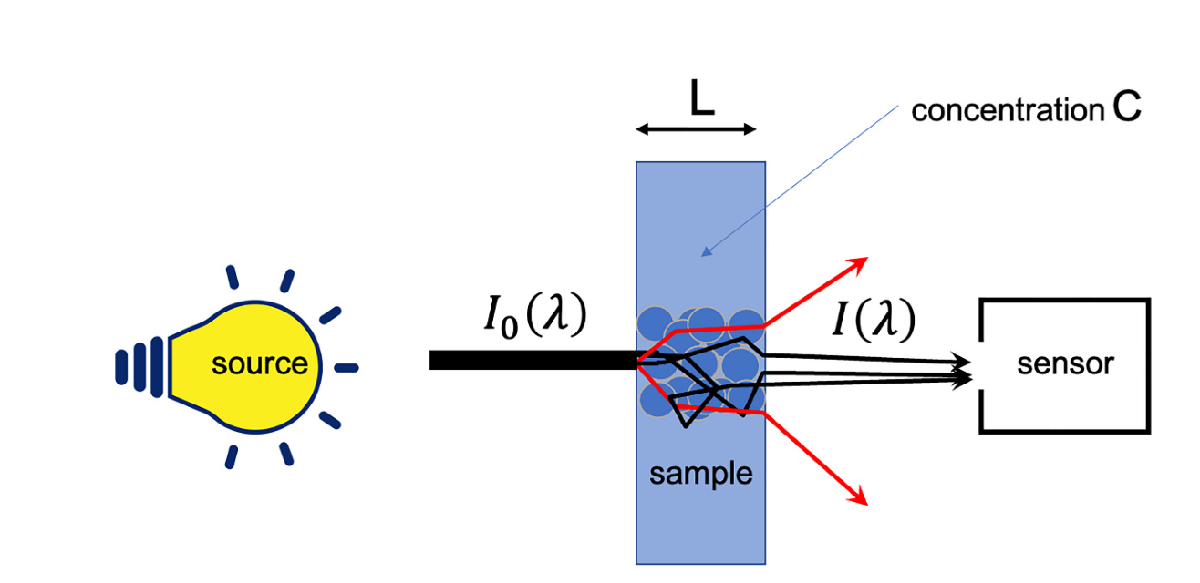

 The purpose of preprocessing is to eliminate  the multiplicative and additive effects in spectra so that  they conform to Beer-Lambert’s law. It is usually admitted that the multiplicative term does not depend on the wavelength and that the additive term does.

# Looking at NIR Spectra

There are plenty of preprocessing methods. Here, we demonstrate a few of them on the corn dataset[2]. Most of these methods have been realized by the existing toolbox, such as the PLS toolbox[3], whose source code can be found on the internet.

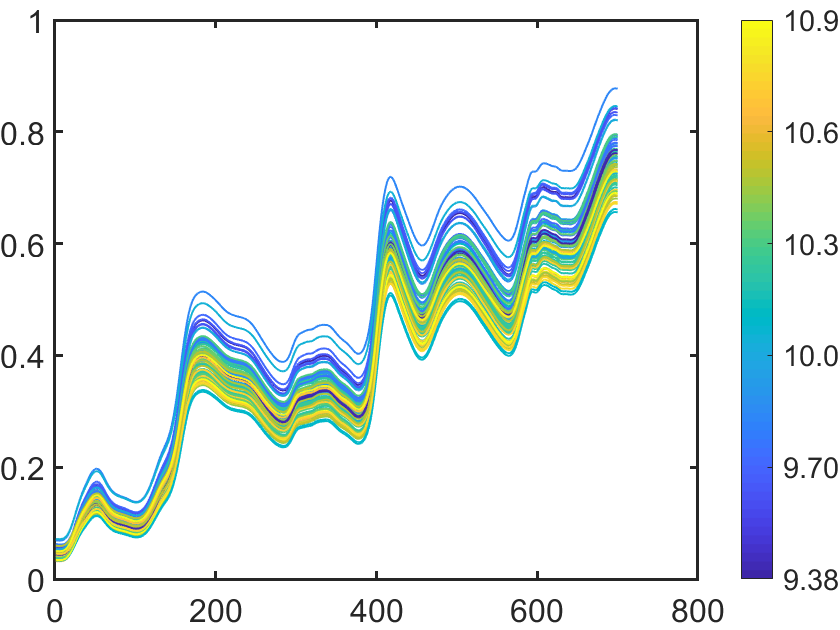

clear;
load corn
X = m5spec.data;
y = propvals.data(:,1); %moisture
%plot(X');
%SCIPlot
plotSpectra(X,y);

# **Moving average window**

A simple smoothing method is to replace the value of each point i in the spectrum by the average of the point values over a window of width w, centered on point i. The window is moved along the spectrum, hence the name moving average window or boxcar filter.

To accelerate the computing, it is worth to use matrix operation to replace the 'conv'.

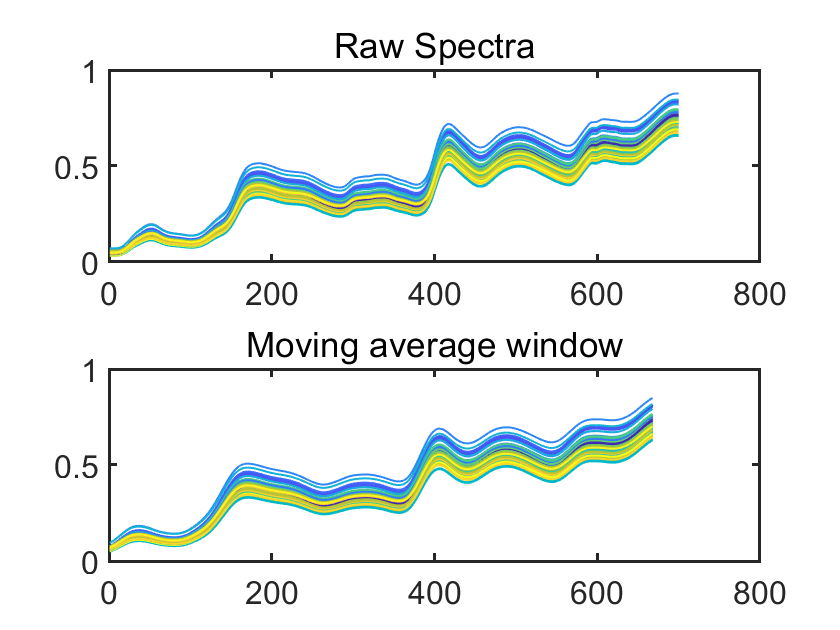

ws = 33;
tmp = [];
filter1 = [ones(1,ws)]/ws; 
for i = 1:1:size(X,1)
    tmp(i,:) = conv(X(i,:),filter1,'valid');
end
figure;
subplot(2,1,1);
plotSpectra(X,y);
title("Raw Spectra");
colorbar('off');
subplot(2,1,2);
plotSpectra(tmp,y);
title("Moving average window");
colorbar('off');

# **Savitsky-Golay method**

The [Savitzky-Golay algorithm](http://adsabs.harvard.edu/abs/1964AnaCh..36.1627S) is based on a moving window that fit a polynomial curve of fixed degree to the spectral data. It is assumed that the fitted values are a better estimate than the measured ones and therefore that some noise is being removed in the process. Function savgol can be found in PLS TOOLBOX.

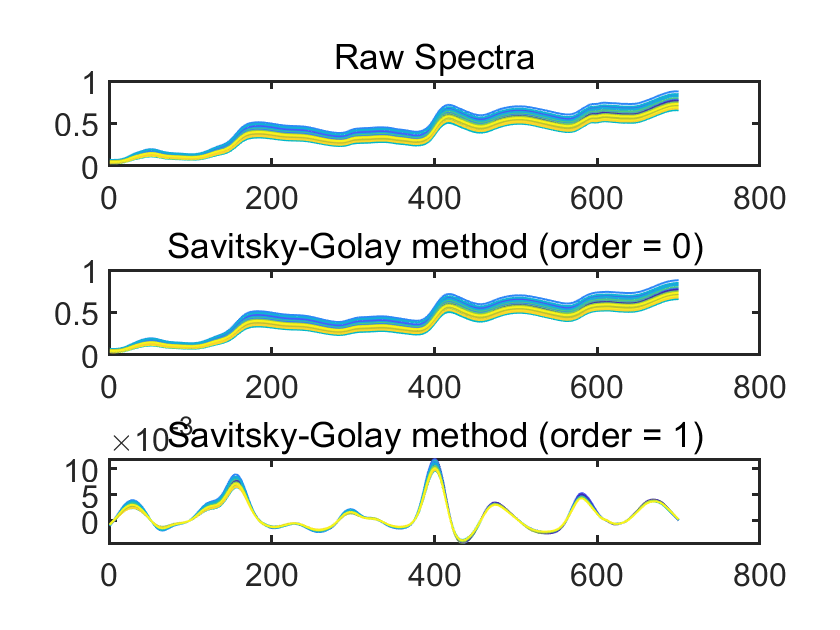

tmp1 = [];
tmp2= [];
for i = 1:1:size(X,1)
    tmp1(i,:) = savgol(X(i,:),33,2,0); 
    tmp2(i,:) = savgol(X(i,:),33,2,1); 
end
figure;
subplot(3,1,1);
plotSpectra(X,y);
title("Raw Spectra");
colorbar('off');
subplot(3,1,2);
plotSpectra(tmp1,y);
title("Savitsky-Golay method (order = 0)");
colorbar('off');
subplot(3,1,3);
plotSpectra(tmp2,y);
title("Savitsky-Golay method (order = 1)");
colorbar('off');

# Detrending

The intensity of NIR spectra alway increases with wavelength. Baseline removal aims at resetting all spectra on a common baseline. Baseline correction methods are generally simple and often preserve the main spectral shape. However, this is not always the case with more advanced baseline removal methods. In some cases, baseline removal techniques can distorts the real proportions between absorbance peaks and therefore, caution should be used when interpreting the results[4]. 

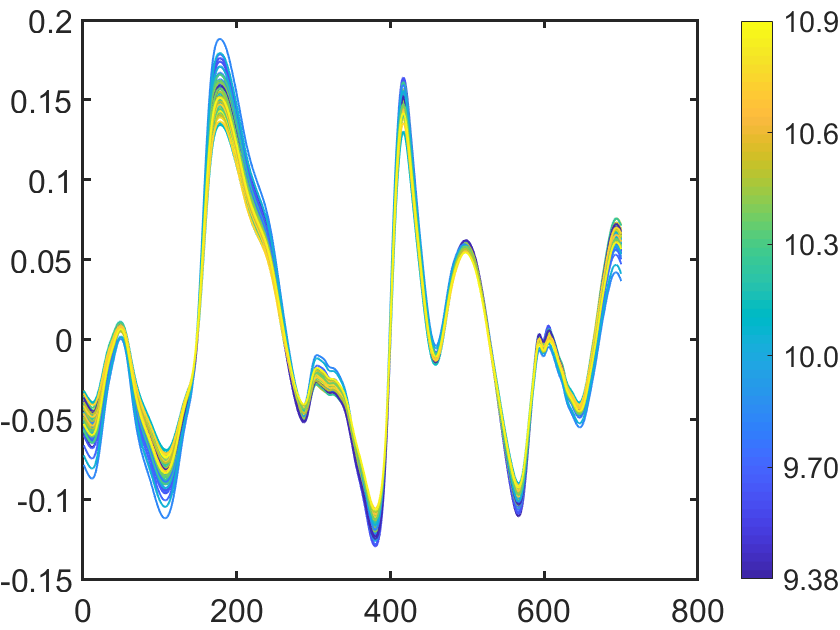

tmp = baseline(X,1:700,1:700);
figure;
plotSpectra(tmp,y);

# Reference

1. Roger, J.-M.; Mallet, A.Marini, F. Preprocessing NIR Spectrafor Aquaphotomics. Molecules 2022,27, 6795. https://doi.org/10.3390/

molecules27206795

2.https://eigenvector.com/resources/data-sets/

3.https://eigenvector.com/software/pls-toolbox/

4. https://guifh.github.io/RNIR/Baseline.html